# 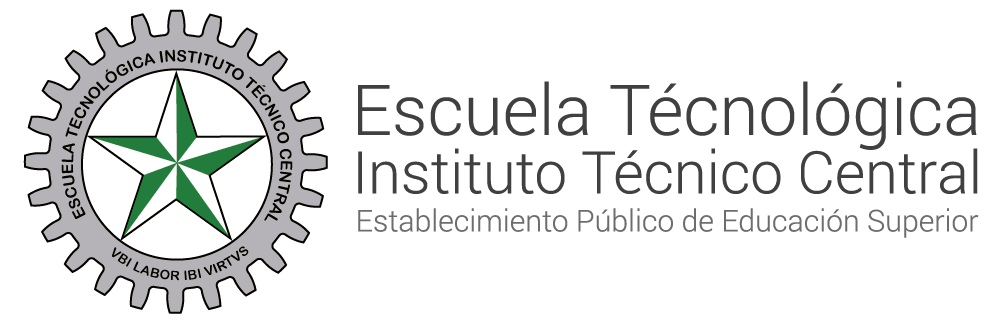

**SISTEMAS DE CONTROL II  **

# **Solución ecuaciones diferenciales **

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO MS.c

**OBJETIVO** Comprender los sistemas de primer y segundo orden en el dominio del tiempo discreto.

En el contexto de sistemas lineales e invariantes en el tiempo (LTI), que son fundamentales en la teoría de control, un sistema de primer orden se define por su respuesta a un impulso unitario. La función de un sistema de primer orden en el dominio de la frecuencia (para sistemas continuos) o en el dominio Z (para sistemas discretos) tiene la forma general:

Para sistemas continuos:


$$G\left(s\right)=\frac{k}{\textrm{Ts}+1}$$


Donde K es la ganancia del sistema y T es la constante de tiempo del sistema.

**Ejercicio**

Encuentre la función de transferencia para el siguiente circuito

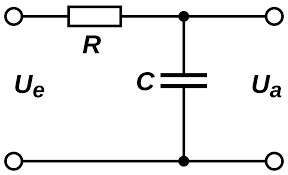

Donde 


$$\begin{array}{l}
y\left(t=0\right)=0\\
V_{\textrm{in}} =X\left(t\right)\\
V_{\textrm{out}} =Y\left(t\right)\\
R=1\Omega \\
C=1F
\end{array}$$


Calcular la respuesta al impulso y al escalón unitario y graficar

## Solución 

Por definición una función de transferencia esta dado por  la siguiente expresión:


$$H\left(S\right)=\frac{e_o }{e_i }$$


Se pueden usar como referencia la segunda ley de Kirchhoff:


$$\sum_{k=1}^n V_k =0$$


En donde $V_k$ es el voltaje en cada uno de los componentes del circuito. Por lo anterior el voltaje de $e_i$ se puede determinar de la siguiente manera:


$$\textrm{Vi}=e_i =V_R +V_C$$


Por otra parte, se puede observar que el voltaje de salida es el voltaje en el condensador, por lo que se puede asumir que:


$$e_o =V_C$$


Ahora con lo anterior, se procede a hallar la función de transferencia:


$$H=\frac{e_o }{e_i }=\frac{V_C }{V_R +V_C }$$


Sin embargo, es importante notar que las ecuaciones aún se encuentran en el dominio del tiempo. Para expreserar la función de transferencia de manera más útil en sistemas dinámicos, se debe aplicar la transformada de Laplace, lo que permite trabajar en el dominio de la frecuencia s:


$$H\left(s\right)=L\left(H\right)$$


En donde:


$$L\left\lbrace \textrm{VR}\right\rbrace =R$$


Siendo R una constante, la trasnformada de laplace de una constante se mantiene constante.


$$L\left\lbrace \textrm{VC}\right\rbrace =\frac{1}{\textrm{sC}}$$


Siendo el voltaje en C una derivada

por lo que resulta: 


$$H\left(s\right)=\frac{e_o }{e_i }=\frac{\frac{1}{\mathrm{sC}}}{R+\frac{1}{\mathrm{sC}}}$$


multiplicando el númerador y el denominador por $\textrm{sC}$ resulta la función de transferencia en terminos de la variable s:


$$H\left(S\right)=\frac{e_o }{e_i }$$


Código Matlab

A continuación definimos las variables "symbolics" R, L, C y s para resolver el problema utilizando matlab.

syms R L C s 
V_R = R ;
V_C = 1/(C*s);
e_o=V_C

$$e\_o = \frac{1}{C\,s}$$

Definimos e_i

e_i=V_R+V_C

$$e\_i = R+\frac{1}{C\,s}$$

H = e_o/e_i;
simplify(H)

$$ans = \frac{1}{C\,R\,s+1}$$

Ahora, Sabiendo que $H\left(s\right)=\frac{e_o }{e_i }=\frac{1}{\mathrm{CRs}+1}$ y que nos solicitan calcular la respuesta al impulso (o delta de dirac) y al escalón unitario, reemplazamos $e_i \;$por sus respectivas transformadas de laplace:

- 
$$L\left\lbrace \delta \right\rbrace =1$$


y 

- 
$$L\left\lbrace U\left(t\right)\right\rbrace =\frac{1}{s}$$


Por lo que resulta 

- $Y\left(s\right)=1*\frac{\frac{1}{\mathrm{sC}}}{R+\frac{1}{\mathrm{sC}}}$$$ para el impulso

y 

- $Y\left(s\right)=\frac{1}{s}*$$\frac{\frac{1}{\mathrm{sC}}}{R+\frac{1}{\mathrm{sC}}}$ para el escalon

respectivamente. Finalmente (Solo para el caso de la respuesta al escalón unitario) se aplican fracciones parciales:

- 
$$Y\left(s\right)=\frac{1}{s}*$$

$$\frac{\frac{1}{\mathrm{sC}}}{R+\frac{1}{\mathrm{sC}}}=\frac{1}{s}-\frac{1}{s+\frac{1}{\mathrm{RC}}}$$
  

Finalmenten aplicamos transformada inversa de laplace y obtenemos:


$$L\left\lbrace Y\left(s\right)=1*\frac{\frac{1}{\mathrm{sC}}}{R+\frac{1}{\mathrm{sC}}}\right\rbrace =y\left(t\right)=e^{-t}$$


y


$$L\left\lbrace Y\left(s\right)=\frac{1}{s}-\frac{1}{s+\frac{1}{\mathrm{RC}}}\right\rbrace =y\left(t\right)=1-e^{-t}$$


Ahora procedemos a simular y graficar en matlab:

**Respuesta al impulso**

numerator = [1];
denominator = [1 1];
Y_s = tf(numerator,denominator)


Y_s =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties


[r,p,k] = residue(numerator,denominator)

r = 1

p = -1


k =

     []



Y_s_fract=r(1)/(s-p(1))

$$Y\_s\_fract = \frac{1}{s+1}$$

syms t;
f = ilaplace(Y_s_fract, s, t)

$$f = {\mathrm{e}}^{-t}$$

**Finalmente Graficamos**

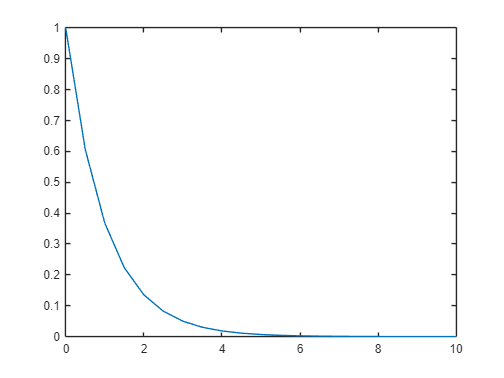

t = 0:0.5:10; 
y_t=exp(-t);
plot(t,y_t);

**Respuesta al Escalón unitario**

numerator = [1];
denominator = [1 1];
escalon=[1 0];
Y_s = tf(numerator,conv(denominator,escalon))


Y_s =
 
     1
  -------
  s^2 + s
 
Continuous-time transfer function.
Model Properties


[r,p,k] = residue(numerator,conv(denominator,escalon))

r =     -1
     1


p =     -1
     0



k =

     []



Y_s_fract=r(1)/(s-p(1))+r(2)/(s-p(2))

$$Y\_s\_fract = \frac{1}{s}-\frac{1}{s+1}$$

syms t;
f = ilaplace(Y_s_fract, s, t)

$$f = 1-{\mathrm{e}}^{-t}$$

#### Finalmente Graficamos

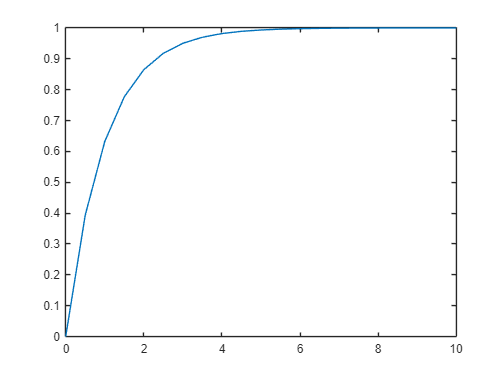

t = 0:0.5:10; 
y_t=1-exp(-t);
plot(t,y_t);

# Taller

- Encuentre y grafique la respuesta a la rampa y grafique.